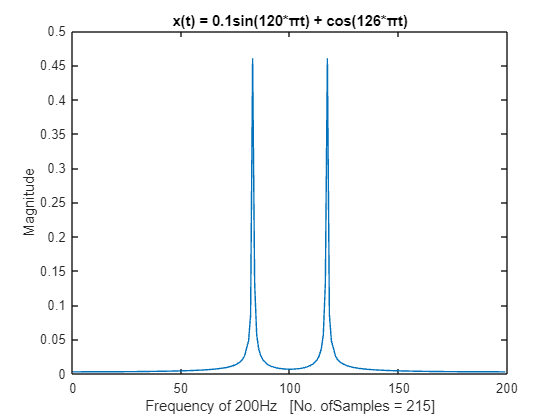

t4= 0:1/200:(214/200);
% 200 since given in question

alpha = 3; A = 160; B = 166;
N4 = 215;
x = 0.1*sin(A*pi*t4) + cos(B*pi*t4) ;

dft4 = fft(x);
mag4 = abs(dft4);

freq4 = (0:N4-1) * (200 / N4);



plot(freq4 , mag4/N4)
title('x(t) = 0.1sin(120*πt) + cos(126*πt)')
xlabel('Frequency of 200Hz   [No. ofSamples = 215]')
ylabel('Magnitude')

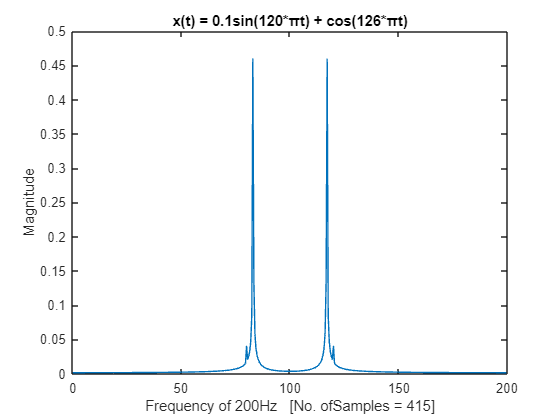

ta4= 0:1/200:(414/200);
% 200 since given in question

alpha = 3; A = 160; B = 166;
N4a = 415;
xa = 0.1*sin(A*pi*ta4) + cos(B*pi*ta4) ;

dft4a = fft(xa);
mag4a = abs(dft4a);

freq4a = (0:N4a-1) * (200 / N4a);



plot(freq4a , mag4a/N4a)

title('x(t) = 0.1sin(120*πt) + cos(126*πt)')
xlabel('Frequency of 200Hz   [No. ofSamples = 415]')
ylabel('Magnitude')

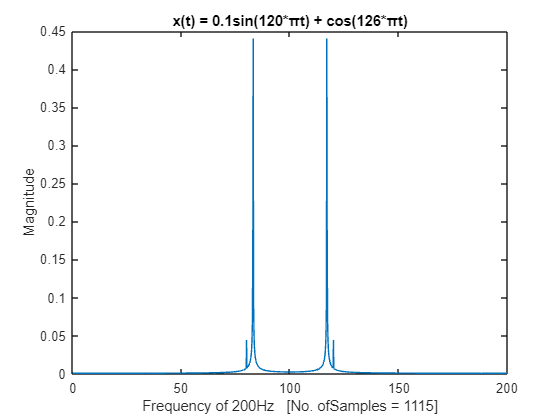

tb4= 0:1/200:(1114/200);
% 200 since given in question

alpha = 3; A = 160; B = 166;
N4b = 1115;
xb = 0.1*sin(A*pi*tb4) + cos(B*pi*tb4) ;

dft4b = fft(xb);
mag4b = abs(dft4b);

freq4b = (0:N4b-1) * (200 / N4b);



plot(freq4b , mag4b/N4b)

title('x(t) = 0.1sin(120*πt) + cos(126*πt)')
xlabel('Frequency of 200Hz   [No. ofSamples = 1115]')
ylabel('Magnitude')

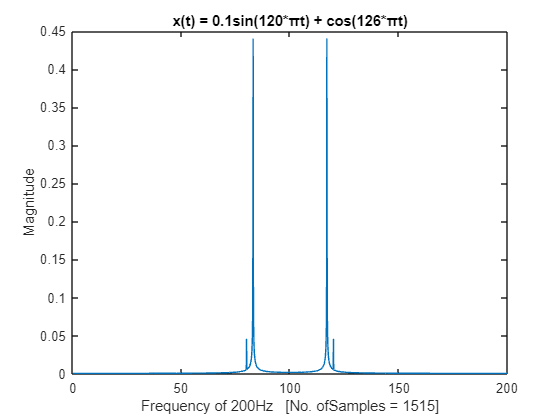

tc4= 0:1/200:(1514/200);
% 200 since given in question

alpha = 3; A = 160; B = 166;
N4c = 1515;
xc = 0.1*sin(A*pi*tc4) + cos(B*pi*tc4) ;

dft4c = fft(xc);
mag4c = abs(dft4c);

freq4c = (0:N4c-1) * (200 / N4c);



plot(freq4c , mag4c/N4c)

title('x(t) = 0.1sin(120*πt) + cos(126*πt)')
xlabel('Frequency of 200Hz   [No. ofSamples = 1515]')
ylabel('Magnitude')

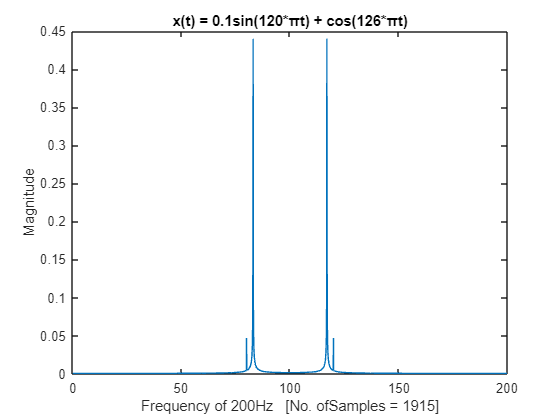

td4= 0:1/200:(1914/200);
% 200 since given in question

alpha = 3; A = 160; B = 166;
N4d = 1915;
xd = 0.1*sin(A*pi*td4) + cos(B*pi*td4) ;

dft4d = fft(xd);
mag4d = abs(dft4d);

freq4d = (0:N4d-1) * (200 / N4d);



plot(freq4d , mag4d/N4d)

title('x(t) = 0.1sin(120*πt) + cos(126*πt)')
xlabel('Frequency of 200Hz   [No. ofSamples = 1915]')
ylabel('Magnitude')

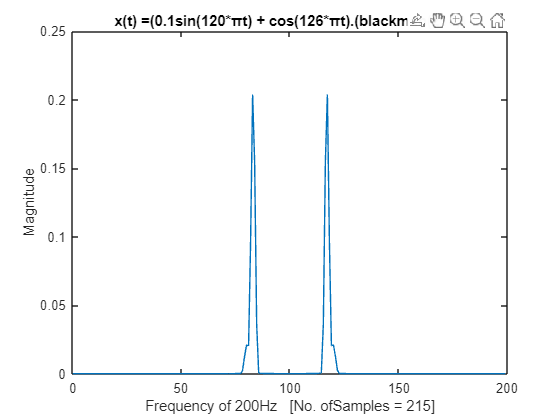


N4 = 215;
x = (0.1*sin(A*pi*t4) + cos(B*pi*t4)).*(transpose(blackman(215))) ;

dft4 = fft(x);
mag4 = abs(dft4);

freq4 = (0:N4-1) * (200 / N4);



plot(freq4 , mag4/N4)

title('x(t) =(0.1sin(120*πt) + cos(126*πt).(blackman(215))')
xlabel('Frequency of 200Hz   [No. ofSamples = 215]')
ylabel('Magnitude')

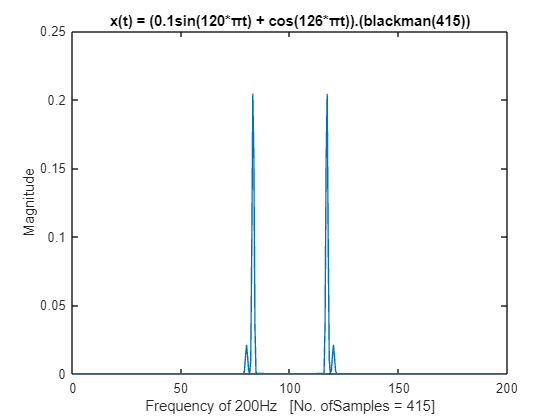


N4a = 415;
xa =( 0.1*sin(A*pi*ta4) + cos(B*pi*ta4)).*(transpose(blackman(415))) ;

dft4a = fft(xa);
mag4a = abs(dft4a);

freq4a = (0:N4a-1) * (200 / N4a);



plot(freq4a , mag4a/N4a)
title('x(t) = (0.1sin(120*πt) + cos(126*πt)).(blackman(415))')
xlabel('Frequency of 200Hz   [No. ofSamples = 415]')
ylabel('Magnitude')

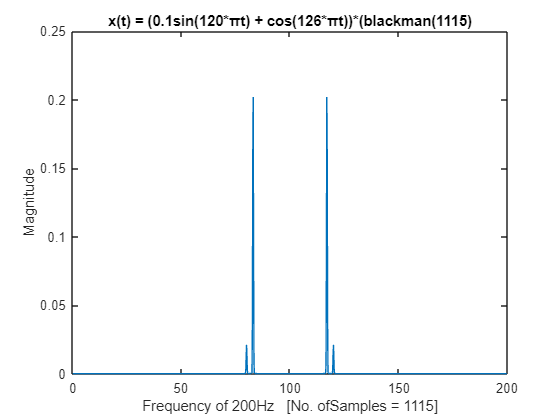


xb = (0.1*sin(A*pi*tb4) + cos(B*pi*tb4)).*(transpose(blackman(1115))) ;

dft4b = fft(xb);
mag4b = abs(dft4b);

freq4b = (0:N4b-1) * (200 / N4b);



plot(freq4b , mag4b/N4b)

title('x(t) = (0.1sin(120*πt) + cos(126*πt))*(blackman(1115)')
xlabel('Frequency of 200Hz   [No. ofSamples = 1115]')
ylabel('Magnitude')

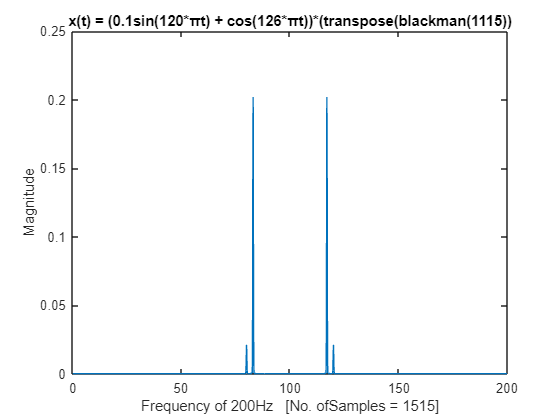


xc = (0.1*sin(A*pi*tc4) + cos(B*pi*tc4)).*(transpose(blackman(1515))) ;

dft4c = fft(xc);
mag4c = abs(dft4c);

freq4c = (0:N4c-1) * (200 / N4c);



plot(freq4c , mag4c/N4c)

title('x(t) = (0.1sin(120*πt) + cos(126*πt))*(transpose(blackman(1115))')
xlabel('Frequency of 200Hz   [No. ofSamples = 1515]')
ylabel('Magnitude')

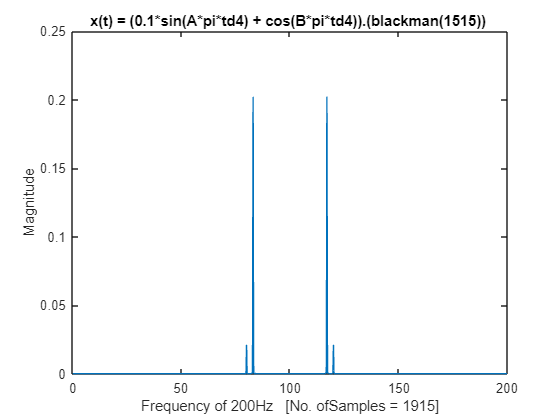


N4d = 1915;
xd1 = (0.1*sin(A*pi*td4) + cos(B*pi*td4)).*(transpose(blackman(1915))) ;

dft4d1 = fft(xd1);
mag4d1 = abs(dft4d1);

freq4d = (0:N4d-1) * (200 / N4d);



plot(freq4d , mag4d1/N4d)

title('x(t) = (0.1*sin(A*pi*td4) + cos(B*pi*td4)).(blackman(1515)) ')
xlabel('Frequency of 200Hz   [No. ofSamples = 1915]')
ylabel('Magnitude')

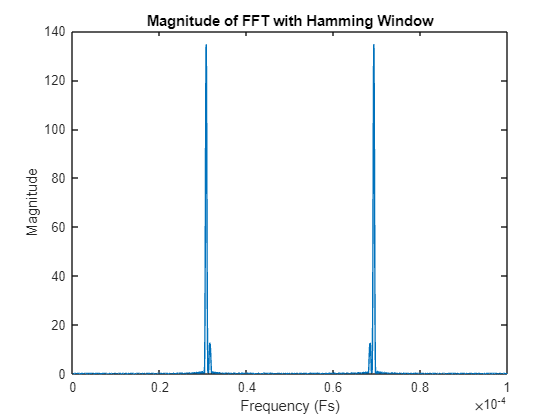

%q4
data = load('Exp4Data3.txt');
Fs = 1; 
T=1/Fs;
t=0:T:duration-T;
N = length(data);

%q4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (Fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 3.07e-05    6.93e-05


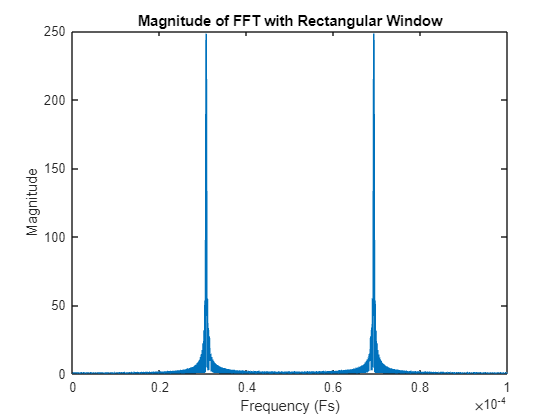


%q4(b)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';

n= 10000;
fft_new1 = fft(data_window_rect, n);
freq = (0:n-1) * (Fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new1));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new1), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Rectangular Window: 3.07e-05    6.93e-05
